Week 14 Recitation: Images

Basics:

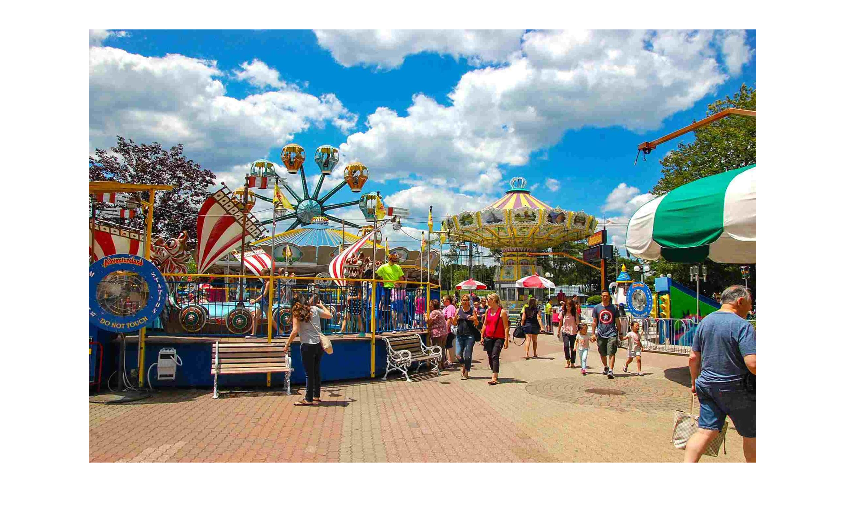

black = [0 0 0];
white = [255 255 255];

% Basic Functions
img = imread('amusementPark.jpg');
imwrite(img, 'newFilename.png');

imshow('amusementPark.jpg')

Splicing

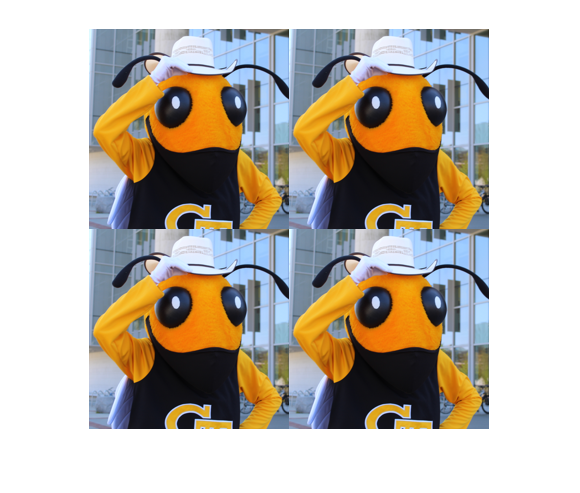

img = imread('buzzes.png');
% topHalf = arr(1:floor(end/2),:)
topHalf = img(1:floor(end/2),:,:);
% img(r, c, l)

justB = img(1:end/4,:,:);
justB2 = img(end/2+1:end*3/4,:,:);
buzzes = [justB; justB2];
imshow(buzzes)

Resizing

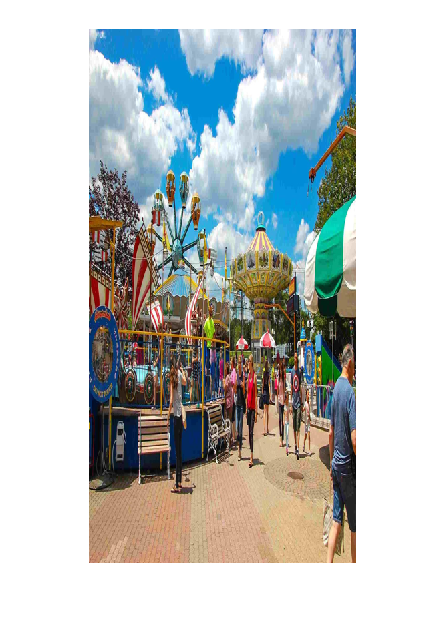

img = imread('buzzes.png');
[rows, cols,~] = size(img);
img2 = imread('amusementPark.jpg');
reSized = imresize(img2, [rows, cols]);
imshow(reSized)

Greenscreening

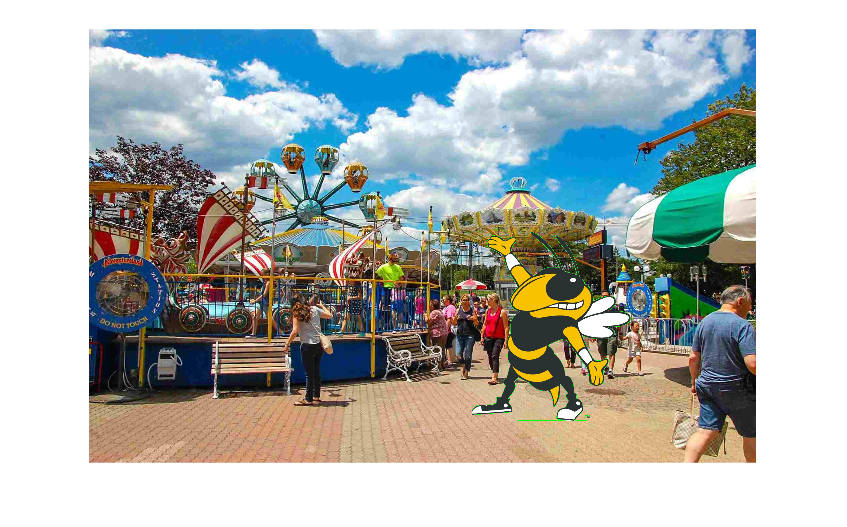

img = imread('greenScreenBuzz.png');
img2 = imread('amusementPark.jpg');
red = img(:,:,1);
green = img(:,:,2);
blue = img(:,:,3);
greens = red == 0 & green == 255 & blue == 0;
superMask = cat(3, greens, greens, greens);
img(superMask) = img2(superMask);
imshow(img)

imwrite(img, 'newBuzz.png')

Grayscaling:

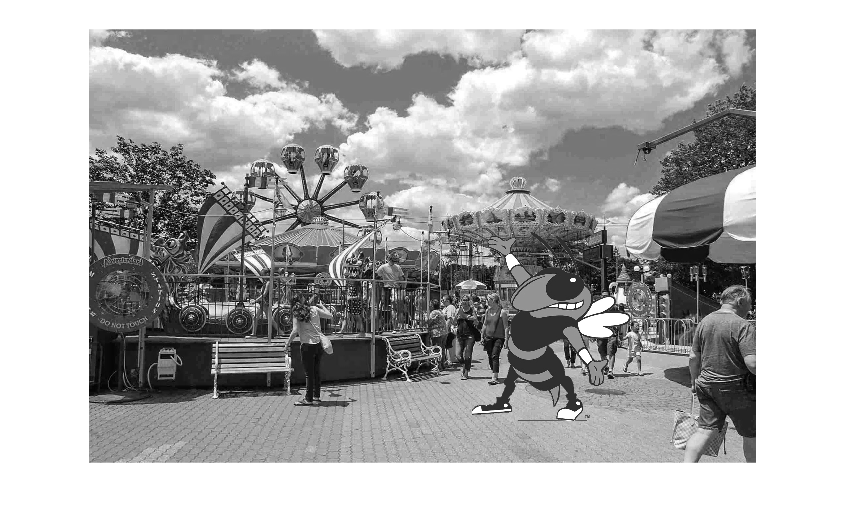

img = imread('newBuzz.png');
red = img(:,:,1);
green = img(:,:,2);
blue = img(:,:,3);
%gray = (double(red)+double(blue)+ double(green))/3;
gray = mean(double(img), 3)
grayPic = cat(3, uint8(gray), uint8(gray), uint8(gray));
imwrite(grayPic, 'grayed.png')
imshow('grayed.png')

Rotations

img = imread('amusementPark.jpg')
% 90 Degree
r = img(:, end:-1:1, 1)
g = img(:, end:-1:1, 2)
b = img(:, end:-1:1, 3)
rot = cat(3, r', g', b')
rot9 = rot90(img, 1)

% 180 Degree
r = img(:, end:-1:1, 1)
g = img(:, end:-1:1, 2)
b = img(:, end:-1:1, 3)

